# **FORRÅR 2016 EKSAMEN**

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

En kontinuert stokastisk variabel $X$har følgende fordelingsfunktion


$$F_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & 2\ge x\\
k\cdot x-\frac{2}{3} & 2<x\le 5\\
1 & 5<x
\end{array}\right\rbrack \right\rbrace$$


## 1.1 TÆTHEDSFUNKTION

For at vise at tæthedsfunktionen er givet ved


$$f_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & 2\ge x\\
k & 2<x\le 5\\
0 & 5<x
\end{array}\right\rbrack \right\rbrace$$


Anvendes, at


$$f_X \left(x\right)=\frac{\textrm{d}}{\textrm{d}x}F_X \left(x\right)$$


syms x k

a = 0;
b = k * x - (2/3);
c = 1;

diff(a), diff(b), diff(c)


ans =

     []



$$ans = k$$


ans =

     []



Da $\lbrack \rbrack$ betyder at værdien er 0 er tæthedsfunktionen $f_X \left(x\right)$hermed eftervist at være korrekt.

## **1.2 GYLDIG TÆTHEDSFUNKTION**

For at bestemme for hvilken værdi af $k$ hvor $f_X \left(x\right)$ er en gyldig tæthedsfunktionen anvendes, at 


$$\int_{-\infty }^{\infty } f_X \left(x\right)\mathrm{dx}=1$$


Da gælder i dette tilfælde, at


$$\int_a^b f_X \left(x\right)=1$$


hvor $a=2$ og $b=5$.


$$\int_2^5 f_X \left(x\right)=1\Rightarrow \int_2^5 k=1$$


Hvilket giver at for værdien af k lig med


$$k=\frac{1}{3}$$


Opnåes en gyldig tæthedsfunktion.

## 1.3 SKITSE AF TÆTHEDSFUNKTION

En skitse af tæthedsfunktionen vises i matlab.

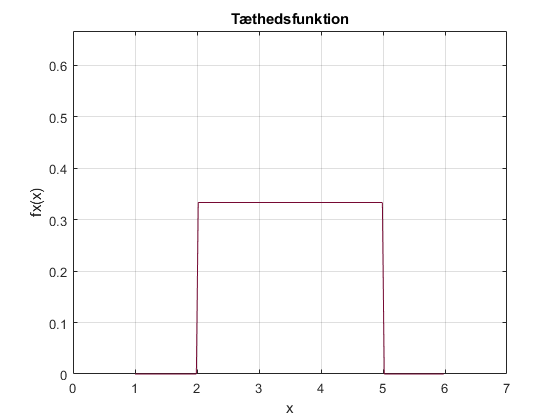

a = 2;
b = 5;
x = a-1:(b-a)/100:b+1;
fx = unifpdf(x, a, b);

figure(1)
plot(x, fx, 'Color', Color.DeepCleret);
axis([a-2, b+2, 0, 2/(b-a)]);
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')

## 1.4 SANDSYNLIGHED

For at bestemme sandsynligheden $P\left(x\ge 3\right)$antages, at $k=3$ og der anvendes følgende


$$P\left(x\ge 3\right)=1-P\left(x<3\right)$$



$$P\left(x\ge 3\right)=1-F_X \left(3\right)$$


k = 1/3;
Fx = @(x) k*x-(2/3);

Probability = 1 - Fx(3)

Probability = 0.6667

Dermed er sandsynligheden $P\left(x\ge 3\right)$bestemt til at være $\frac{2}{3}$.

## 1.5 FORVENTNINGSVÆRDI & VARIANS

For at bestemme forvetningsværdien anvendes, at 


$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}\Rightarrow E\left\lbrack X\right\rbrack =\int_2^5 x\cdot k$$


hvor værdien for $k$ antages, at være $\frac{1}{3}$.

k = 1/3;
fx = @(x) x * k;
EstimationValue = sym(integral(fx, 2, 5))

$$EstimationValue = \frac{7}{2}$$

Forventningsværdien er dermed bestemt til, at være $\frac{7}{2}$. Variansen bestemmes dernæst ved følgende,


$$\mathrm{Var}\left(x\right)=\int_{-\infty }^{\infty } \left(x-\bar{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


fx = @(x) x.^2 * k;
Variance = sym(integral(fx, 2, 5)) - EstimationValue^2

$$Variance = \frac{3}{4}$$

Variansen er dermed bestemt til, at være $\frac{3}{4}$.

# **2 STOKASTISKE PROCESSER**

En kontinuer stokastisk process er givet ved


$$X\left(t\right)=w+4$$


Hvor $w$ er normalfordelt efter $N\left(5,1\right)$.

## 2.1 REALISERING

For at skitsere en realisering af den kontinuere process vides det, at


$$\sigma^2 =1,\mu =5$$


Dertil kan realiseringen laves ved brug af matlab.

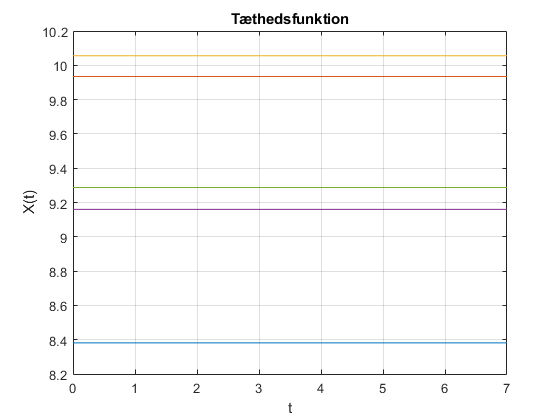

t = 0:1:7;
mu = 5;
sigma = sqrt(1);

Realisation = [[],[],[],[],[]];

for n = 1:5
   Realisation(n, :) = (ones(1, 8) * (sigma * randn + mu)) + 4;
end 

figure(3)
plot(t, Realisation(1, :));
hold on
plot(t, Realisation(2, :));
plot(t, Realisation(3, :));
plot(t, Realisation(4, :));
plot(t, Realisation(5, :));
grid on
title('Tæthedsfunktion')
ylabel('X(t)')
xlabel('t')
hold off

## 2.2 MIDDELVÆRDI OG VARIANS

For at bestemme middelværdien for ensemble anvendes, at


$$E\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack w+4\right\rbrack =E\left\lbrack w\right\rbrack +E\left\lbrack 4\right\rbrack$$


Ensemble.MeanValue = mu + 4;

Variansen kan bestemmes som


$$\mathrm{Var}\left(X\left(t\right)\right)=\mathrm{Var}\left\lbrack w+4\right\rbrack =\mathrm{Var}\left\lbrack w\right\rbrack +\mathrm{Var}\left\lbrack 4\right\rbrack$$


Ensemble.Variance = sigma^2 + 0;

Ensemble

Ensemble = struct with fields:
    MeanValue: 9
     Variance: 1


Dermed er middelværdien bestemt til at være 9 og variansen bestemt til at være 1.

## 2.3 REALISERINGS MIDDELVÆRDI OG VARIANS

Real.Mean = mean(Realisation(1, :));
Real.Variance = round(var(Realisation(1, :)), 10);

Real

Real = struct with fields:
        Mean: 8.3813
    Variance: 0


Middelværdi og variansen for en udvalgt realisering er bestemt til at være værdierne vist ovenfor.

## 2.4 PROCESSEN

Da ensemble middelværdi og varianse er uafhængig af tiden og samtidig konstant er processen WSS. Processen er ikke ergodisk da middelværdien og variansen af en realisering ikke siger noget om en middelværdi og varians for hele processen.

# **3 SANDSYNLIGHED**

**A: GRAVID FØDTE EN PIGE I 2012**

**B: GRAVID FØDTE EN DRENG**

**C: GRAVID FØDTE ET BARN OVER 4000 G.**

20.2% af alle nyfødte drenge vejede i 2012 over 4000g. 12.8% af nyfødte piger vejede i 2012 over 4000g.


$$P\left(C|B\right)=0\ldotp 202$$



$$P\left(C|A\right)=0\ldotp 128$$


## 3.1 HÆNDELSE A

For at bestemme hvad sandsynligheden er for hændelse A, vides det, at der blev født 29.785 drenge og 28.131 piger i 2012. Da anvendes den relative frekvens som er bestemt ved følgende udtryk.


$$P\left(A\right)=\frac{N_A }{N}=\frac{28\ldotp 131}{28\ldotp 131+29\ldotp 785}$$


Boys = 29785;
Girls = 28131;

A = Girls / (Girls + Boys)

A = 0.4857

Sandsynligheden for hændelse **A** er dermed bestemt til at være 48.57%.

## 3.2 TOTALE SANDSYNLIGHED

Den totale sandsynlighed for hændelse **C** kan bestemmes ved, at anvende følgende.


$$P\left(A\right)=P\left(A\cap B\right)+P\left(A\cap \overline{B} \right)$$



$$P\left(A\right)=P\left(A|B\right)\cdot P\left(B\right)+P\left(A|\overline{B} \right)\cdot P\left(\overline{B} \right)$$


Der antages i dette tilfælde for opgaven, at $P\left(B\right)=1-P\left(A\right)$ da den modsatte hændelse at at få en pige vil være at få en dreng.

B = 1 - A;
CGivenB = 0.202;
CGivenA = 0.128;

C = CGivenA * A + CGivenB * B

C = 0.1661

Den totale sandsynlighed for hændelse **C** er dermed bestemt til at være 16.61%.

## 3.3 BETINGET SANDSYNDLIGHED

For at bestemme hvad sansynligheden for at den fødende fik en pige, hvis det oplyses, at hendes barn vejede over 4000g ved fødslen anvendes, at


$$P\left(A|C\right)=\frac{P\left(C|A\right)\cdot P\left(A\right)}{P\left(C\right)}$$


AGivenC = (CGivenA * A) / C

AGivenC = 0.3744

Dermed er sandsynligheden for, at den fødende fik en pige givet at barnet vejde over 4000g ved fødslen, bestemt til at være 37.44%.

# **4 STATISTIK**

Der måles højden på studerende i en klasse, der består af 19 kvinder og 35 mænd. Højderne antages at være normalfordelt. Middelværdien for kvinder i klassen er $\hat{\mu_1 } =1\ldotp 68m$, med en estimeret varians på $\sigma_1^2 =0\ldotp 10$. Middelværdien for mænd i klassen er $\hat{\mu_1 } =1\ldotp 78m$, med en estimeret varians på $\sigma_1^2 =0\ldotp 20$.

Women.Sigma = 0.1;
Women.Mu = 1.68;
Women.Amount = 19;

Men.Sigma = 0.20;
Men.Mu = 1.78;
Men.Amount = 35;

## **4.1 HYPOTESE**

Der opstilles en hypotese test for at bestemme om middelværdien af mænd og kvinder i klassen er den samme.


$$H_0 :$$
  
$$\mu_1 =\mu_2$$



$$H_1 :$$
  
$$\mu_1 \not= \mu_2$$


## **4.2 STATISTIK TEST**

Da varianserne er ukendte og data er normal-fordelt anvendes en t-test på forskellen af middelværdiernerne.

## **4.3 ESTIMERING AF VÆRDIER**

Estimeringen af forskellen i middelværdierne kan bestemmes som følgende.


$$\delta^ˆ =|\overline{x_1 } -\overline{x_2 } |$$


Delta = abs(Women.Mu - Men.Mu)

Delta = 0.1000

Forskellen i middelværdierne er bestemt til at være 0.1. Dernæst til at bestemme forskellen i standard afvigelsen og dertil  anvendes, at


$$s^2 =\frac{1}{n_1 +n_2 -2}\left\lbrack \left(n_1 -1\right)\cdot s_1^2 +\left(n_2 -1\right)\cdot s_2^2 \right\rbrack$$


PooledVariance = sqrt((1 / (Women.Amount + Men.Amount - 2)) ...
    * ((Women.Amount - 1)*Women.Sigma + (Men.Amount - 1)*Men.Sigma))

PooledVariance = 0.4067

Forskellen i standard afvigelsen er dermed bestemt til at være 0.4067.

## **4.4 T-TEST**

Der anvendes nu en t-test til test af hypotesen. For at undersøge om NULL hypotesen kan afvises med et signifikansniveau på 0.05 anvendes, at


$$t=\frac{\left(\overline{x_1 } -\overline{x_2 } \right)-\delta }{s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}},\;\;p=2\cdot \left(1-t_{\mathrm{cdf}} \left(|t|,n_1 +n_2 -2\right)\right)$$


t = (Delta - 0) / (PooledVariance * sqrt(1/Women.Amount + 1/Men.Amount));

p = 2 * (1 - tcdf(abs(t), Women.Amount + Men.Amount -2))

p = 0.3921

NULL hypotesen kan ikke afvises da $p>0\ldotp 05$. 

## **4.5 KONFIDENSINTERVAL**

For at finde 95% konfidens intervallet for $\delta$ anvendes, at 


$$\delta_{\pm } =\left(\overline{x_1 } -\overline{x_2 } \right)\pm t_0 \cdot s\cdot \sqrt{\frac{1}{n_1 }+\frac{1}{n_2 }}$$


TZero = tinv(0.975, Women.Amount + Men.Amount - 2)

TZero = 2.0066


Step = TZero * PooledVariance * sqrt(1/Women.Amount + 1/Men.Amount);

Interval.Min = Delta - Step;
Interval.Max = Delta + Step;

Interval

Interval = struct with fields:
    Min: -0.1325
    Max: 0.3325


Konfidensintervallet for $\delta$ er dermed bestemt til at være [-0.1325; 0.3325].